## SIR Generalization

Tmax = 50;
TStep = 0.05;

alpha = 0.5;
beta = 0.1;
nu = 0.01;
mu = 0.02;
delta = 0.01;
p = 0.1;

S = 995;
I = 5;
R = 0;
N = S + I + R;

### Prepare vectors

Sprogress = zeros(Tmax/TStep+1,1);
Iprogress = zeros(Tmax/TStep+1,1);
Rprogress = zeros(Tmax/TStep+1,1);
Nprogress = zeros(Tmax/TStep+1,1);
Tprogress = zeros(Tmax/TStep+1,1);

## Numerical Integration

i = 1;
for t = 0:TStep:Tmax
    s_ = (1-p) * nu * N - alpha * S * I/N - mu * S + delta * R;
    i_ = alpha * S * I/N - beta * I - mu * I;
    r_ = nu * p * N + beta * I - mu * R -  delta * R;
    n_ = (nu - mu) * N;

    S = S + s_ * TStep;
    I = I + i_ * TStep;
    R = R + r_ * TStep;
    N = N + n_ * TStep;

    Sprogress(i) = S;
    Iprogress(i) = I;
    Rprogress(i) = R;
    Nprogress(i) = N;
    Tprogress(i) = t;

    i = i + 1;
end

## Visualize the Results

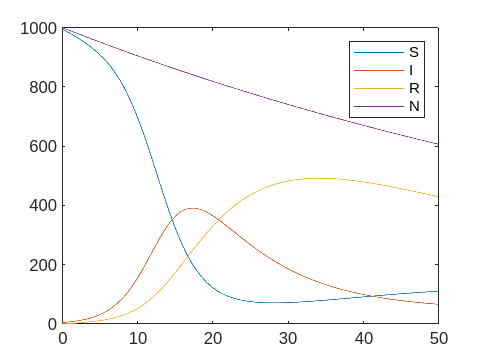

figure;
plot(Tprogress, [Sprogress, Iprogress, Rprogress, Nprogress]);
legend('S', 'I', 'R', 'N');